clear; clc;

addpath(genpath('functions'));
filePath = "D:\Research\experiments\Siemens results\20240529 Siemens\DYA_A1J40.csv";
dataNum = 8;

siemensData = load_siemens_data(filePath,dataNum);
% 转换为输出类型
% siemensData = table2array(siemensData);

% 清除临时变量
clear opts tmp tmpName tmpNameInd


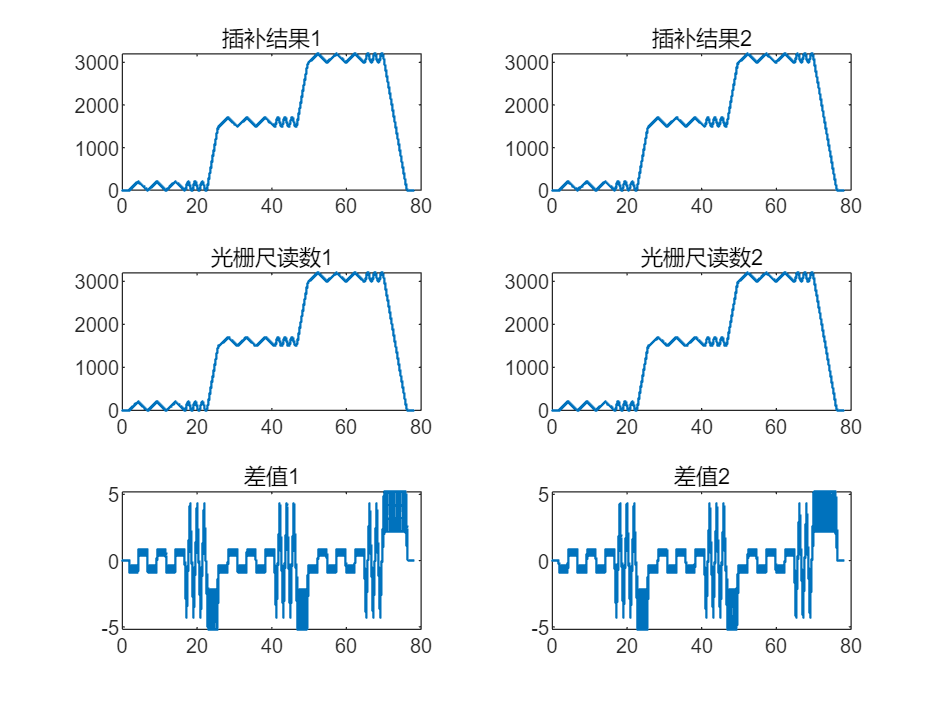

fig0 = figure('Name', '插补结果和光栅尺读数');
t1 = tiledlayout(3, 2);
nexttile(t1,1);
plot(siemensData.time, siemensData.int1, '-o','MarkerSize', 0.5);
hold on;
title('插补结果1');
nexttile(t1,2);
plot(siemensData.time, siemensData.int2, '-o', 'MarkerSize', 0.5);
title('插补结果2');
nexttile(t1,3);
plot(siemensData.time, siemensData.disp1, '-o', 'MarkerSize', 0.5);
hold on;
title('光栅尺读数1');
nexttile(t1,4);
plot(siemensData.time, siemensData.disp2, '-o', 'MarkerSize', 0.5);
title('光栅尺读数2');
nexttile(t1,5);
plot(siemensData.time, siemensData.disp1 - siemensData.int1, '-o', 'MarkerSize', 0.5);
hold on;
title('差值1');
nexttile(t1,6);
plot(siemensData.time, siemensData.disp2 - siemensData.int2, '-o', 'MarkerSize', 0.5);
title('差值2');

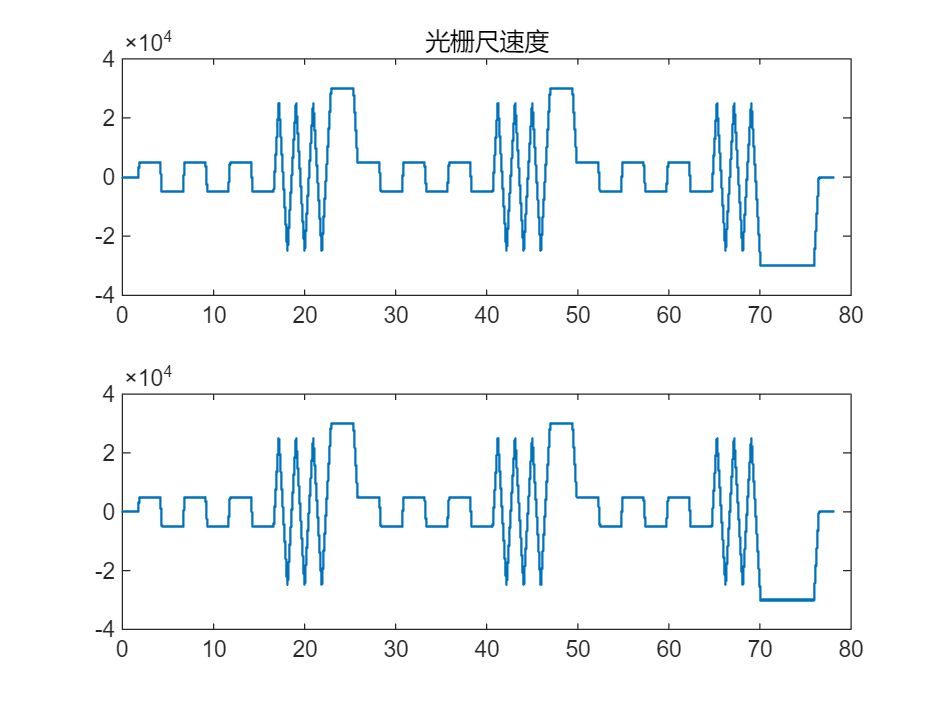


fig2 = figure('Name', '光栅尺速度');
siemensVelotime = (siemensData.time(2:end) + siemensData.time(1:end - 1)) / 2;
tiledlayout(2,1);
nexttile;
simensVelo1 = 60*(siemensData.disp1(2:end) - siemensData.disp1(1:end - 1)) ./ (siemensData.time(2:end) - siemensData.time(1:end - 1));
plot(siemensVelotime, simensVelo1, '-o', 'MarkerSize', 0.5);
hold on;
title('光栅尺速度');
nexttile;
simensVelo2 = 60*(siemensData.disp2(2:end) - siemensData.disp2(1:end - 1)) ./ (siemensData.time(2:end) - siemensData.time(1:end - 1));
plot(siemensVelotime, simensVelo2, '-o', 'MarkerSize', 0.5);

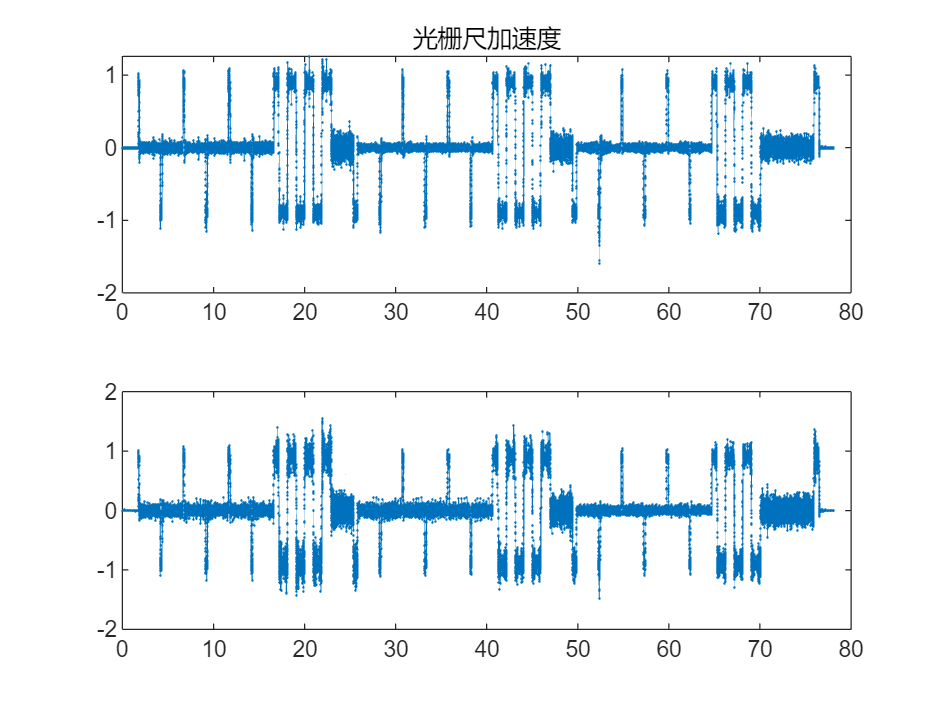


fig3 = figure('Name','光栅尺加速度');
siemensAcceltime = (siemensVelotime(2:end) + siemensVelotime(1:end - 1)) / 2;
tiledlayout(2,1);
nexttile;
simensAccel1 = (simensVelo1(2:end) - simensVelo1(1:end - 1)) ./ 60000 ./ (siemensVelotime(2:end) - siemensVelotime(1:end - 1));
plot(siemensAcceltime, simensAccel1, '-o', 'MarkerSize', 0.5);
hold on;
title('光栅尺加速度');
nexttile;
simensAccel2 = (simensVelo2(2:end) - simensVelo2(1:end - 1)) ./ 60000 ./ (siemensVelotime(2:end) - siemensVelotime(1:end - 1));
plot(siemensAcceltime, simensAccel2, '-o' , 'MarkerSize' , 0.5);

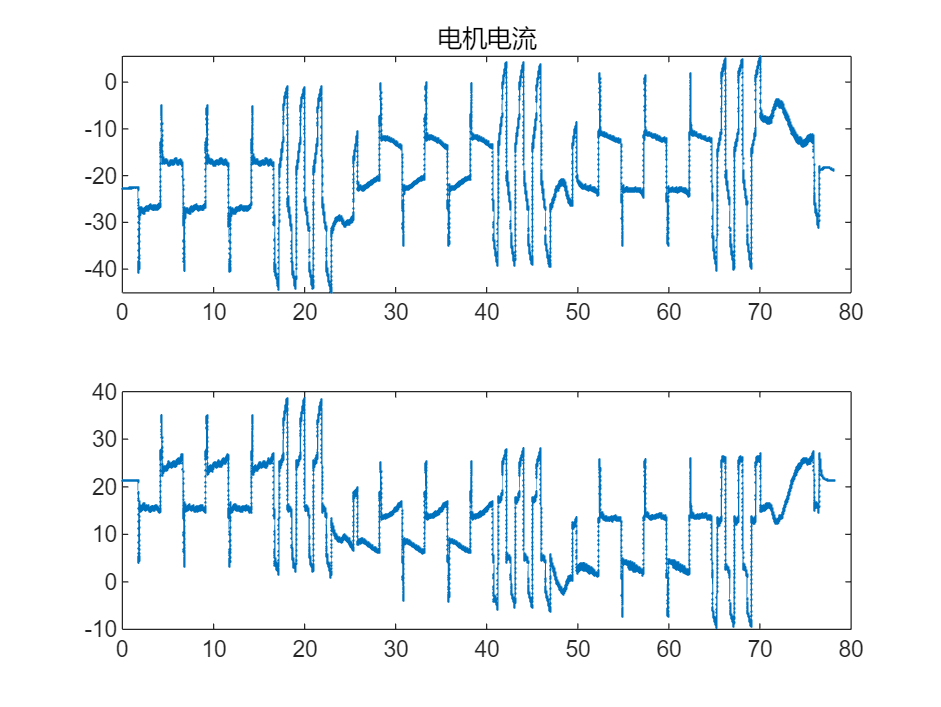



fig4 = figure('Name','电机电流');
tiledlayout(2,1);
nexttile
plot(siemensData.time,siemensData.current1,'-o','MarkerSize',0.5);
title('电机电流');
nexttile;
plot(siemensData.time,siemensData.current2,'-o','MarkerSize',0.5);

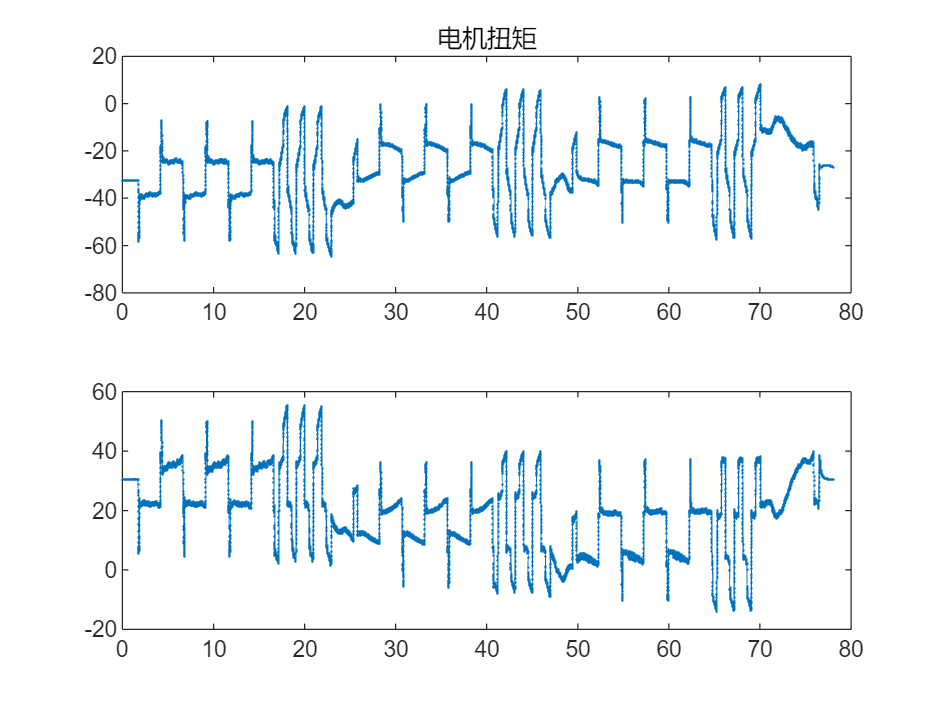



fig5 = figure('Name','电机扭矩');
tiledlayout(2,1);
nexttile
plot(siemensData.time,siemensData.torque1,'-o','MarkerSize',0.5);
title('电机扭矩');
nexttile;
plot(siemensData.time,siemensData.torque2,'-o','MarkerSize',0.5);


rmpath(genpath('functions'));